## Caracterización de clases por distancia

load matlab_clasificacion\data_dist.mat
% Generación de dos subconjuntos
X1 = X(G==1,:);
X2 = X(G==2,:);
% Generación de puntos equiespaciados
[pX,pY]=meshgrid(-8:0.2:14); 
P=[pX(:) pY(:)]; 
% Distanciade cada punto a la media
pD1=pdist2(mean(X1),P); 
pD2=pdist2(mean(X2),P); 
% Clasificar los puntos eb la clase cuya media en más cercana
pG=3*ones(size(pD1));
pG(pD1>pD2)=4;
% Ploteo
gplotmatrix([X;P],[],[G pG],'grgr','**..');

- Escribir G == 1 hace que te quedes con la primera mitad de los datos de la muestra.

- Coordenadas en X de la muestra generada con puntos equiespaciados.

- La media del primer subconjunto.

- Lo que se aleja de la media del subconjunto -> distancia.

- Hace que todos los datos que esten más lejos de la media del primer subconjunto sean de la segunda muestra.

- Elementos gráficos para cada subconjunto.

- Si, teniendo en cuenta la distancia euclídea, lo que provoca que se produzcan malas asignaciones, pues la muesta no tiene unas varianzas simétricas para las dos características.

% Distanciade cada punto a la media
pD1=pdist2(mean(X1),P,'cityblock'); 
pD2=pdist2(mean(X2),P,'cityblock'); 
% Clasificar los puntos eb la clase cuya media en más cercana
pG=3*ones(size(pD1));
pG(pD1>pD2)=4;
% Ploteo
gplotmatrix([X;P],[],[G pG],'grgr','**..');

- Es otro tipo de distancias pero, al no tener en cuenta las covarianzas, sigue siendo errónea.

% Matriz de covarianzas
C = 0.5*cov(X1)+0.5*cov(X2);
% Distanciade cada punto a la media
pD1=pdist2(mean(X1),P,'mahalanobis',C); 
pD2=pdist2(mean(X2),P,'mahalanobis',C); 
% Clasificar los puntos eb la clase cuya media en más cercana
pG=3*ones(size(pD1));
pG(pD1>pD2)=4;
% Ploteo
gplotmatrix([X;P],[],[G pG],'grgr','**..');

- La distancia de Mahalanobis, tener en cuenta las covarianza de la muestra, permite detectar mucho mejor las clases, pues esta muestra, a la vista de la gráfica, no tiene una distribución de probabilidad simétrica en sus dos características.

## Distribución de las observaciones

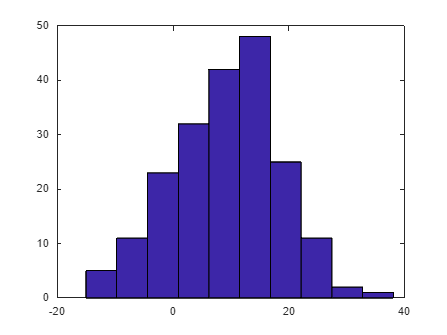

mu1 = 10;
var1 = 9;
r = normrnd(mu1,var1,[1,200]);
hist(r);


m1 = mean(r);
dvt1 = std(r);
disp("Mean: "+m1);

Mean: 9.2845


disp("Standard Deviation: "+dvt1);

Standard Deviation: 9.2302


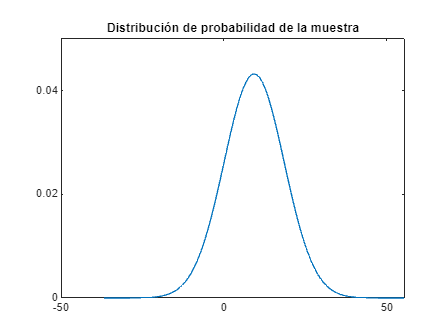


ax = linspace(m1-5*dvt1,m1+5*dvt1,200);
y = normpdf(ax,m1,dvt1);
figure
plot(ax,y)
title('Distribución de probabilidad de la muestra')

- La diferencia es clara en que uno cuenta casos en cierto intervalo, mientras que la segunda normaliza tomando como 1 el subconjunto entero. Además, al colocar en intervalos, se observa como hay saltos que en la distribución de probabilidad no se ven.

- El historgrama podría dividirse entre el número total de muestras y se quedaría normalizado. Para que ambas curvas se parecieran m´sa habría que incrementar la muestra, subir el número de observaciones.

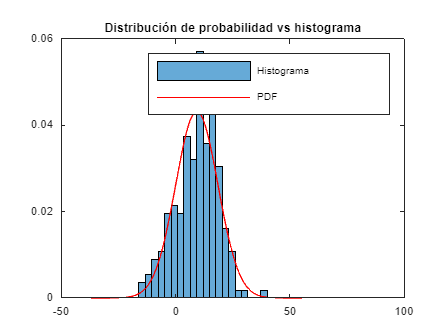

nbins = 20;
figure
histogram(r,nbins,'Normalization','pdf');
hold on
plot(ax,y,'r');
title('Distribución de probabilidad vs histograma');
legend('Histograma','PDF');

Los resultados previos se han obtenido con una muestra de 10000 observaciones.

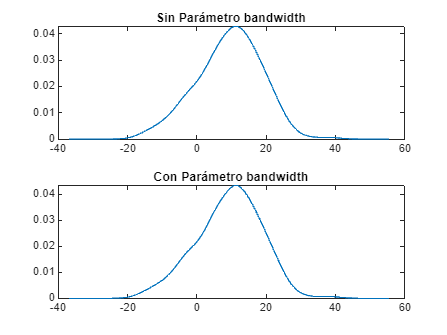

[yr1,xi1] = ksdensity(r,ax);
[yr2,xi2] = ksdensity(r,ax,"Bandwidth",3);
figure
subplot(2,1,1)
plot(xi1,yr1)
title('Sin Parámetro bandwidth')
subplot(2,1,2)
plot(xi2,yr2)
title('Con Parámetro bandwidth')

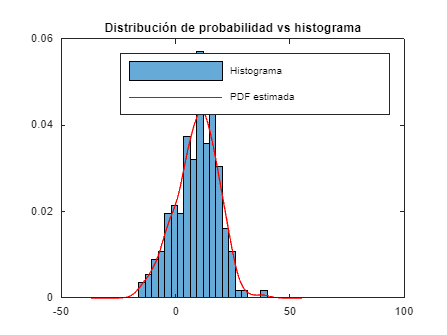

nbins = 20;
figure
histogram(r,nbins,'Normalization','pdf');
hold on
plot(xi2,yr2,'r');
title('Distribución de probabilidad vs histograma');
legend('Histograma','PDF estimada');

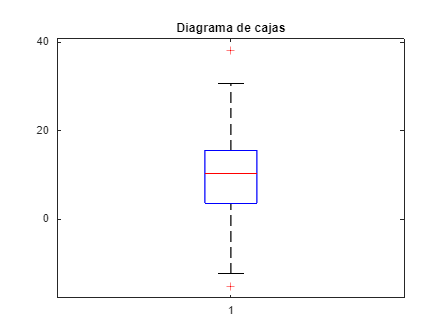

figure
boxplot(r);
title('Diagrama de cajas')

- En este tipo de representación, el grueso de la caja representa los percentiles 25 y 75 con una línea entre ambas que se corresponde al percentil 50 (mediana), además de dos finas líneas que se expanden hasta límites muestrales superiores. Finalmente, por encima de ese límite, se pueden encontrar anomalías.

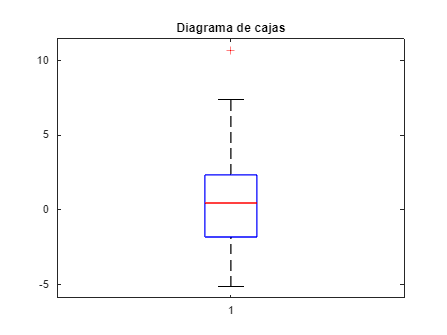

mu2 = 1;
var2 = 3;
r2 = normrnd(mu2,var2,[1,30]);
figure
boxplot(r2);
title('Diagrama de cajas')

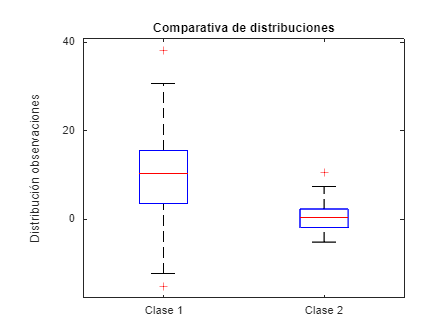

X = [r,r2];
G = [repmat({'Clase 1'},200,1); repmat({'Clase 2'},30,1)];
figure
boxplot(X,G);
title('Comparativa de distribuciones');
ylabel('Distribución observaciones');

- Esta gráfica permite ver que hay una diferencia clara en la distribución de probabilidad de cada una. Se puede ver que, con esta característica se producirían errores. Se debería evaluar alguna otra más.